clc
clear all
close all

Num_Hunters = 11 %input("How many hunters do you own? ")

Num_Hunters = 11

Hunter_Slots = [1 2 1 1 1]

Hunter_Slots =      1     2     1     1     1


Total_Slots = Num_Hunters * Hunter_Slots

Total_Slots =     11    22    11    11    11



Primary = zeros(1,Total_Slots(1));
Secondary = zeros(1,Total_Slots(2));
Melee = zeros(1,Total_Slots(3));    
Back = zeros(1,Total_Slots(4));
Misc = zeros(1,Total_Slots(5));

% Primary Weapons
NumCharge = 2 %input("How many Charge Rifles do you have? ");

NumCharge = 2

NumJigSaw = 2 %input("How many Jigsaw Rifles do you have? ");

NumJigSaw = 2

Charge_Rifle = [50 NumCharge];
Jigsaw_Rifle = [35 NumJigSaw];

Primary_Names = [Charge_Rifle;Jigsaw_Rifle];
for Primary_Weapons = 1 : 2
    Primary = Yield(Primary_Names(Primary_Weapons,:),Primary);
end

% Secondary Weapons
NumBerine = 4 %input("How many Berine Blasters do you have? ");

NumBerine = 4

NumJannus = 1 %input("How many Jannus Mods HB-44 do you have? ");

NumJannus = 1

NumBlaster = 5 %input("How many Standard Issue Blasters do you have? ");

NumBlaster = 5

Berine_Blaster = [30 NumBerine];
Jannus_HB44 = [25 NumJannus];
Standard_Blaster = [10 NumBlaster];

Secondary_Names = [Berine_Blaster;Jannus_HB44;Standard_Blaster];
for Secondary_Weapons = 1 : 3
    Secondary = Yield(Secondary_Names(Secondary_Weapons,:),Secondary);
end

% Melee Weapons
NumVelurian = 1 %input("How many Velurian Sabres do you have? ");

NumVelurian = 1

NumSword = 1 %input("How many Alkavi'r Shortswords do you have? ");

NumSword = 1

NumRayBlade = 2 %input("How many Rayblade do you have? ");

NumRayBlade = 2

Velurian_Sabre = [100 NumVelurian];
Shortsword = [50 NumSword];
Ray_Blade = [50 NumRayBlade];

Melee_Names = [Velurian_Sabre;Shortsword;Ray_Blade];
for Melee_Weapons = 1 : 3
    Melee = Yield(Melee_Names(Melee_Weapons,:),Melee);
end

% Jetpack
NumJetpack = 2 %input("How many jetpacks do you have? ");

NumJetpack = 2

Jetpack = [40 NumJetpack];
Back = Yield(Jetpack,Back);

% Misc
NumFlame = 2 %input("How many flame throwers do you have? ");

NumFlame = 2

NumMapper = 2 %input("How many galaxy mappers do you have? ");

NumMapper = 2

NumBrain = 3 %input("How many Spider Brains do you have? ");

NumBrain = 3

Flame_Thrower = [30 NumFlame];
Galaxy_Mapper = [20 NumMapper];
Spider_Brain = [5 NumBrain];

Misc_Names = [Flame_Thrower;Galaxy_Mapper;Spider_Brain];
for Misc_Weapons = 1 : 3
    Misc = Yield(Misc_Names(Misc_Weapons,:),Misc);
end

Daily_BNTY_Items = sum(Primary) + sum(Secondary) + sum(Back) + sum(Melee) + sum(Misc)

Daily_BNTY_Items = 810

Total_Daily_BNTY = Daily_BNTY_Items + 100 * Num_Hunters

Total_Daily_BNTY = 1910

% A hunter with perfect yield gives 380 $BNTY/day thus a comparison can be
% made between the perfect hunter and the case of the wallet examined.
% 100 = hunter
% 50 = charge rifle
% 60 = 2x berine blasters
% 40 = jetpack
% 100 = Velurian Sabre
% 30 = Flamethrower
% Calculation for Hunter equipment saturation can be taken by finding the
% total $BNTY obtain for you hunters in the perfect case and dividing by
% that to find a percentage
Item_Equip_Percentage_Efficiency = Daily_BNTY_Items/(Num_Hunters*250)*100

Item_Equip_Percentage_Efficiency = 29.4545


% This efficiency can be calcualted per slot as the items are not just all
% bundled together.
Efficiency_Primary = sum(Primary)/(Num_Hunters*Charge_Rifle(1))*100

Efficiency_Primary = 30.9091

Efficiency_Secondary = sum(Secondary)/(Num_Hunters*Berine_Blaster(1))*100

Efficiency_Secondary = 59.0909

Efficiency_Melee = sum(Melee)/(Num_Hunters*Velurian_Sabre(1))*100

Efficiency_Melee = 22.7273

Efficiency_Back = sum(Back)/(Num_Hunters*Jetpack(1))*100

Efficiency_Back = 18.1818

Efficiency_Misc = sum(Misc)/(Num_Hunters*Flame_Thrower(1))*100

Efficiency_Misc = 34.8485


Efficiency_Items = [Item_Equip_Percentage_Efficiency,Efficiency_Primary,Efficiency_Secondary,Efficiency_Melee,Efficiency_Back,Efficiency_Misc]

Efficiency_Items =    29.4545   30.9091   59.0909   22.7273   18.1818   34.8485


labels = {'Average','Primary','Secondary','Melee','Back','Misc'}

labels = 1×6 cell array
    {'Average'}    {'Primary'}    {'Secondary'}    {'Melee'}    {'Back'}    {'Misc'}


bar(Efficiency_Items)
title('Slot Equip Efficiency')
ylabel('Percentage Equip Efficiency')
Rounded = round(Efficiency_Items,2,"significant")

Rounded =     29    31    59    23    18    35


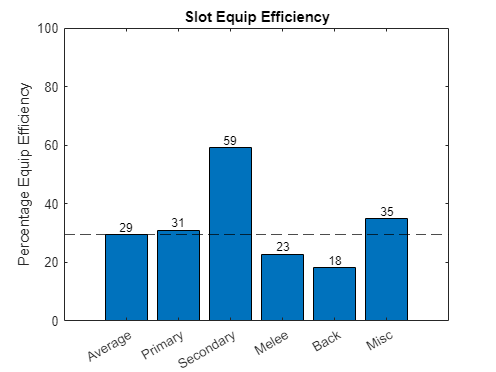

text(linspace(1,6,6),Efficiency_Items,string(Rounded),'FontSize',9,'VerticalAlignment','bottom','HorizontalAlignment','center')
xticklabels(labels)
ylim([0,100])
yline(Item_Equip_Percentage_Efficiency,'k--')


% With this knowledge we are able to determine the yearly rewards of
% holding hunters and their items
Sol_Price = 32.27

Sol_Price = 32.2700

BNTY_Price = 0.00154584

BNTY_Price = 0.0015

Daily_USD = BNTY_Price * Total_Daily_BNTY

Daily_USD = 2.9526

Daily_SOL = Daily_USD / Sol_Price

Daily_SOL = 0.0915

Yearly_USD = 365 * Daily_USD

Yearly_USD = 1.0777e+03

Yearly_SOL = 365 * Daily_SOL

Yearly_SOL = 33.3958

function [y] = Yield(Weapon,Slot)
% Creates a function where the weapon and the type can be inputed and the
% result is an array that tells you how many 
for Equipment = find(abs(Slot)<0.01,1):find(abs(Slot)<0.01,1) + Weapon(2) 
    if Slot(end) == 0
        if Weapon(2) > 0
            if Slot(Equipment) == 0
                Slot(Equipment) = Weapon(1);
            end
        end
        Weapon(2) = Weapon(2) - 1;
    end
end
y = Slot;
end